# 0. Підготовка

clear; close all; clc;

## 1. Завантаження кількох зображень з бібліотеки MATLAB  у різних форматах та їх відображення

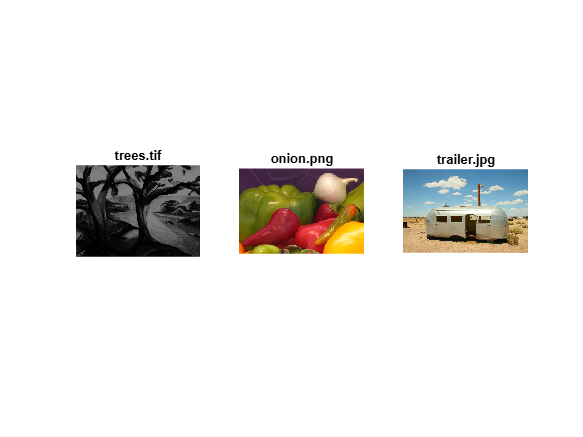

I1 = imread('trees.tif');
I2 = imread('onion.png');
I3 = imread('trailer.jpg');

figure;
subplot(1,3,1), imshow(I1), title('trees.tif');
subplot(1,3,2), imshow(I2), title('onion.png');
subplot(1,3,3), imshow(I3), title('trailer.jpg');

## 2. Завантаження зображення з каталогу і його відображення

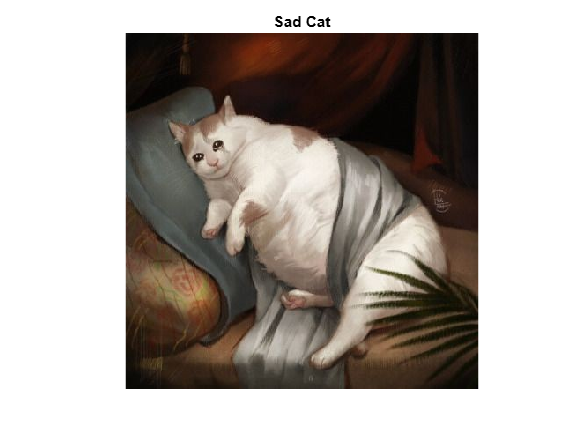

imagePath = 'images/sad_cat.jpg';
I_custom = imread(imagePath);

figure, imshow(I_custom), title('Sad Cat');

## 3. Інформація про завантажені зображення

info1 = imfinfo('trees.tif');
info2 = imfinfo('onion.png');
info3 = imfinfo('trailer.jpg');
info4 = imfinfo('images/sad_cat.jpg');

disp('Info - trees.tif:'); disp(info1);

Info - trees.tif:
  8x1 struct array with fields:

    Filename
    FileModDate
    FileSize
    Format
    FormatVersion
    Width
    Height
    BitDepth
    ColorType
    FormatSignature
    ByteOrder
    NewSubFileType
    BitsPerSample
    Compression
    PhotometricInterpretation
    StripOffsets
    SamplesPerPixel
    RowsPerStrip
    StripByteCounts
    XResolution
    YResolution
    ResolutionUnit
    Colormap
    PlanarConfiguration
    TileWidth
    TileLength
    TileOffsets
    TileByteCounts
    Orientation
    AutoOrientedWidth
    AutoOrientedHeight
    FillOrder
    GrayResponseUnit
    MaxSampleValue
    MinSampleValue
    Thresholding
    Offset
    ImageDescription



disp('Info - onion.png:'); disp(info2);

Info - onion.png:
                  Filename: '/MATLAB/toolbox/images/imdata/onion.png'
               FileModDate: '13-Jul-2023 20:26:02'
                  FileSize: 44638
                    Format: 'png'
             FormatVersion: []
                     Width: 198
                    Height: 135
                  BitDepth: 24
                 ColorType: 'truecolor'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              ImageModTime: '29 Oct 2009 17:11:53 +0000'
           

disp('Info - trailer.jpg:'); disp(info3);

Info - trailer.jpg:
              Filename: '/MATLAB/toolbox/images/imdata/trailer.jpg'
           FileModDate: '14-Oct-2016 15:08:44'
              FileSize: 144847
                Format: 'jpg'
         FormatVersion: ''
                 Width: 1024
                Height: 683
              BitDepth: 24
             ColorType: 'truecolor'
       FormatSignature: ''
       NumberOfSamples: 3
          CodingMethod: 'Huffman'
         CodingProcess: 'Progressive'
               Comment: {}
               XMPData: [1x1 struct]
                  Make: 'Canon'
                 Model: 'Canon EOS 30D'
           Orientation: 1
     AutoOrientedWidth: 1024
    AutoOrientedHeight: 683
           XResolution: 72
           YResolution: 72
        ResolutionUnit: 'Inch'
              Software: 'Adobe Photoshop CS Windows'
              DateTime: '2006:08:26 16:29:09'
      YCbCrPositioning: 'Co-sited'
         DigitalCamera: [1x1 struct]
         ExifThumbnail: [1x1 struct]



disp('Info - sad_cat.jpg:'); disp(info4);

Info - sad_cat.jpg:
              Filename: '/MATLAB Drive/images/sad_cat.jpg'
           FileModDate: '16-Mar-2025 17:34:55'
              FileSize: 25377
                Format: 'jpg'
         FormatVersion: ''
                 Width: 400
                Height: 404
              BitDepth: 24
             ColorType: 'truecolor'
       FormatSignature: ''
       NumberOfSamples: 3
          CodingMethod: 'Huffman'
         CodingProcess: 'Sequential'
               Comment: {}
     AutoOrientedWidth: 400
    AutoOrientedHeight: 404




size_I1 = size(I1);
class_I1 = class(I1);
disp(['Розмір trees.tif: ', num2str(size_I1)]);

Розмір trees.tif: 258  350


disp(['Тип даних trees.tif: ', class_I1]);

Тип даних trees.tif: uint8



size_I2 = size(I2);
class_I2 = class(I2);
disp(['Розмір onion.png: ', num2str(size_I2)]);

Розмір onion.png: 135  198    3


disp(['Тип даних onion.png: ', class_I2]);

Тип даних onion.png: uint8



size_I3 = size(I3);
class_I3 = class(I3);
disp(['Розмір trailer.jpg: ', num2str(size_I3)]);

Розмір trailer.jpg: 683  1024     3


disp(['Тип даних trailer.jpg: ', class_I3]);

Тип даних trailer.jpg: uint8



size_I4 = size(I_custom);
class_I4 = class(I_custom);
disp(['Розмір sad_cat.jpg: ', num2str(size_I4)]);

Розмір sad_cat.jpg: 404  400    3


disp(['Тип даних sad_cat.jpg: ', class_I4]);

Тип даних sad_cat.jpg: uint8


## 4. Збереження завантажених зображень

imwrite(I1, 'images/trees_saved.tif');
imwrite(I2, 'images/onion_saved.png');
imwrite(I3, 'images/trailer_saved.jpg');

## 5. Побудува гістограм для зображень imhist(I)

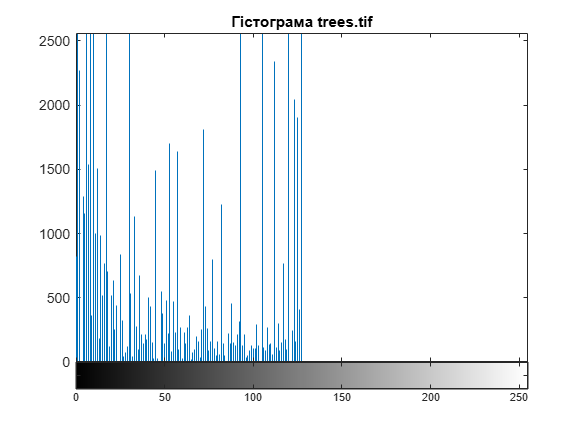

imhist(I1);
title("Гістограма trees.tif");

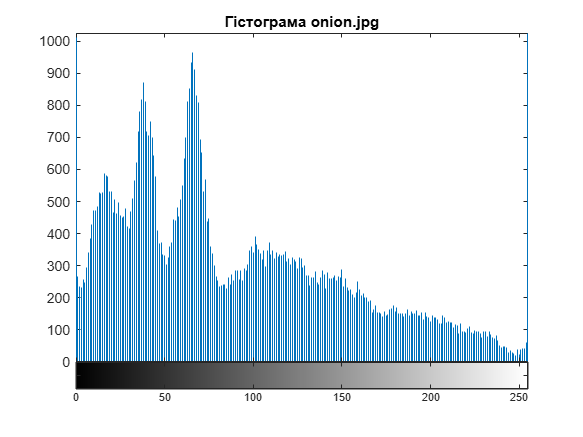

figure;
imhist(I2);
title("Гістограма onion.jpg");

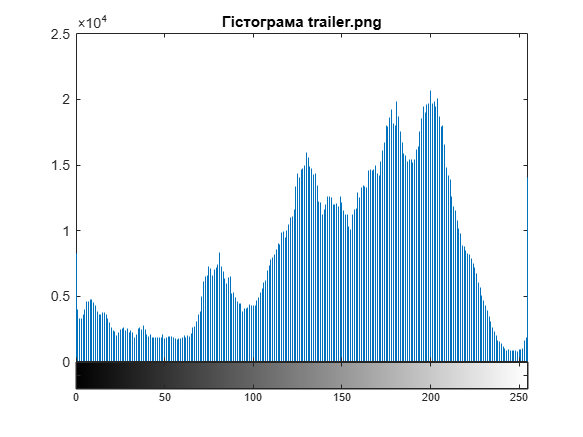

figure;
imhist(I3);
title("Гістограма trailer.png");

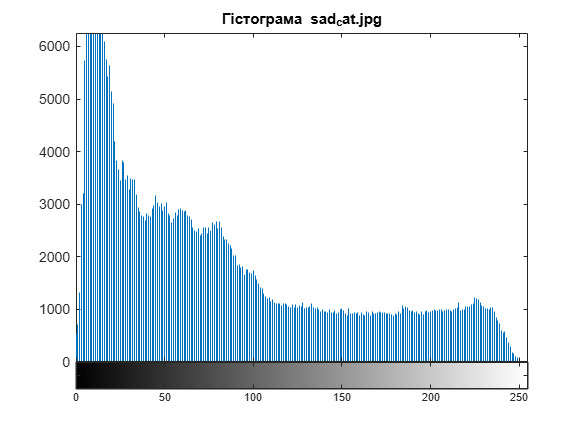

figure;
imhist(I_custom);
title("Гістограма sad_cat.jpg");

figure;

## 6-7. Контрастування зображень (imadjust)

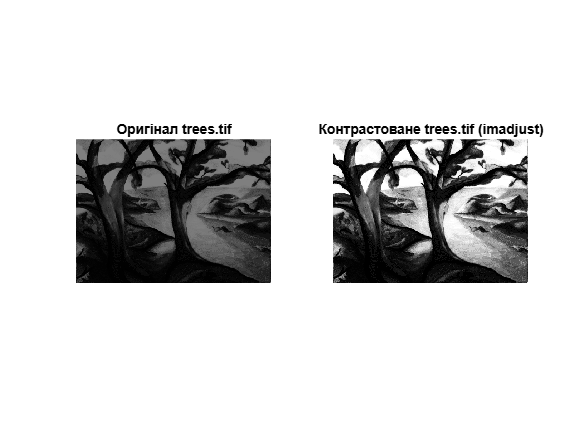

% Для сірого зображення I1 (trees.tif)
I1_adjusted = imadjust(I1);
figure;
subplot(1,2,1), imshow(I1), title('Оригінал trees.tif');
subplot(1,2,2), imshow(I1_adjusted), title('Контрастоване trees.tif (imadjust)');

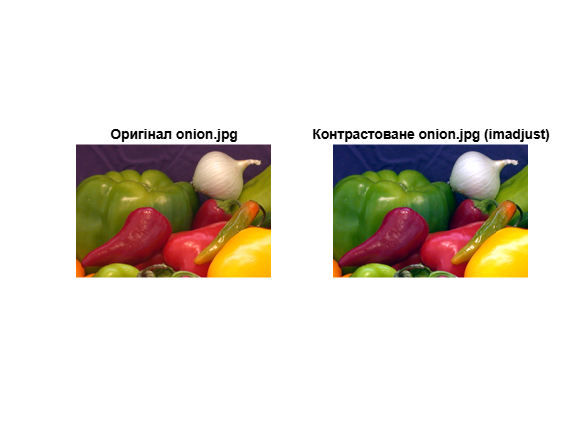


% Для кольорового зображення I2 (onion.jpg)
R = I2(:,:,1);
G = I2(:,:,2);
B = I2(:,:,3);
R_adjusted = imadjust(R);
G_adjusted = imadjust(G);
B_adjusted = imadjust(B);
I2_adjusted = cat(3, R_adjusted, G_adjusted, B_adjusted);
figure;
subplot(1,2,1), imshow(I2), title('Оригінал onion.jpg');
subplot(1,2,2), imshow(I2_adjusted), title('Контрастоване onion.jpg (imadjust)');

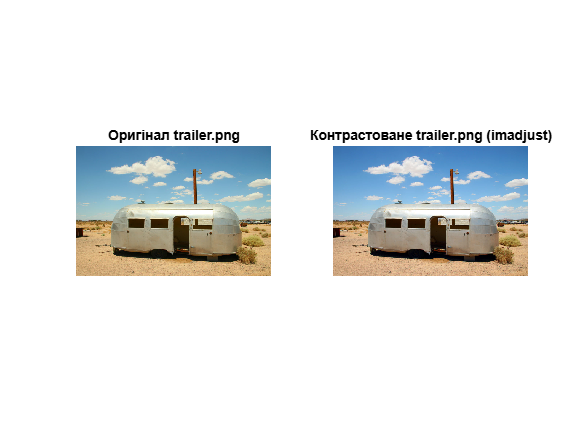


% Для кольорового зображення I3 (trailer.png)
R = I3(:,:,1);
G = I3(:,:,2);
B = I3(:,:,3);
R_adjusted = imadjust(R);
G_adjusted = imadjust(G);
B_adjusted = imadjust(B);
I3_adjusted = cat(3, R_adjusted, G_adjusted, B_adjusted);
figure;
subplot(1,2,1), imshow(I3), title('Оригінал trailer.png');
subplot(1,2,2), imshow(I3_adjusted), title('Контрастоване trailer.png (imadjust)');

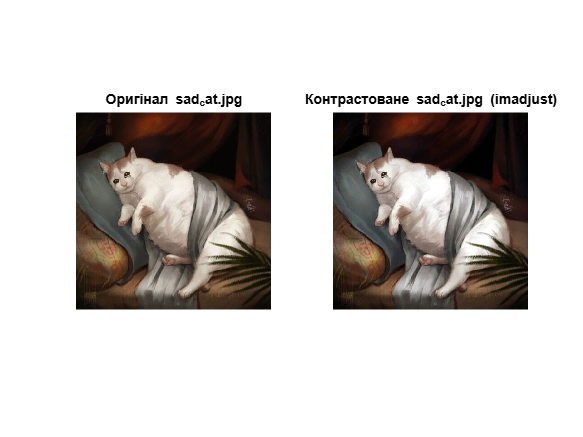


% Для кольорового зображення I_custom (sad_cat.jpg)
R = I_custom(:,:,1);
G = I_custom(:,:,2);
B = I_custom(:,:,3);
R_adjusted = imadjust(R);
G_adjusted = imadjust(G);
B_adjusted = imadjust(B);
I_custom_adjusted = cat(3, R_adjusted, G_adjusted, B_adjusted);
figure;
subplot(1,2,1), imshow(I_custom), title('Оригінал sad_cat.jpg');
subplot(1,2,2), imshow(I_custom_adjusted), title('Контрастоване sad_cat.jpg (imadjust)');

## 8. Негативи зображень

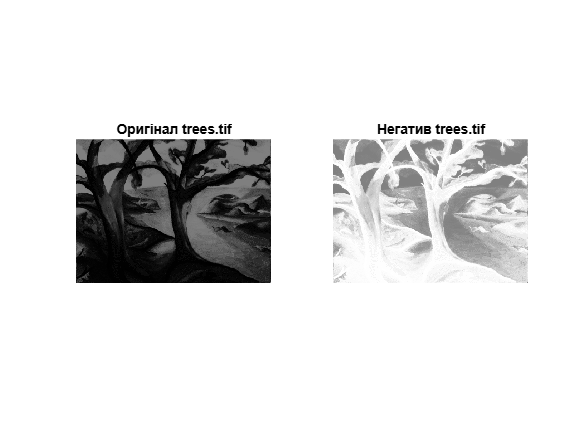

I1_negative = imcomplement(I1);
I2_negative = imcomplement(I2);
I3_negative = imcomplement(I3);
I_custom_negative = imcomplement(I_custom);

figure;
subplot(1,2,1), imshow(I1), title('Оригінал trees.tif');
subplot(1,2,2), imshow(I1_negative), title('Негатив trees.tif');

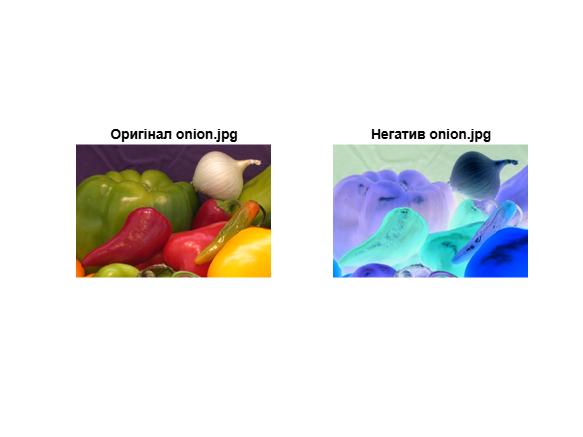


figure;
subplot(1,2,1), imshow(I2), title('Оригінал onion.jpg');
subplot(1,2,2), imshow(I2_negative), title('Негатив onion.jpg');

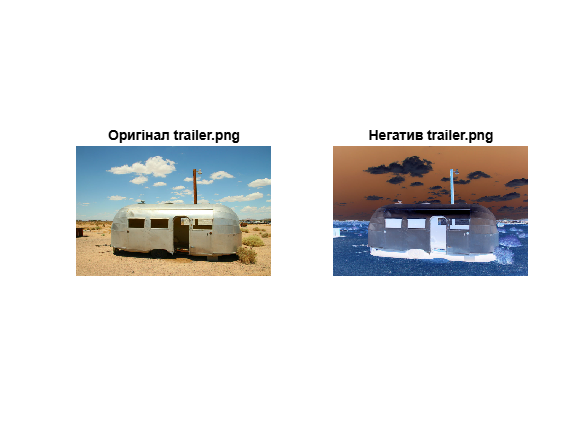


figure;
subplot(1,2,1), imshow(I3), title('Оригінал trailer.png');
subplot(1,2,2), imshow(I3_negative), title('Негатив trailer.png');

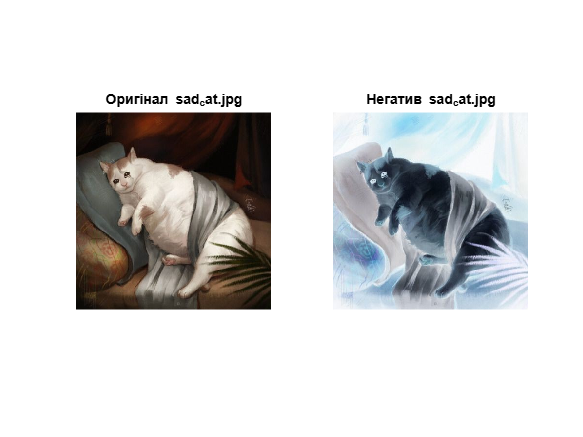


figure;
subplot(1,2,1), imshow(I_custom), title('Оригінал sad_cat.jpg');
subplot(1,2,2), imshow(I_custom_negative), title('Негатив sad_cat.jpg');

## 9. Приклади використання параметрів imadjust

help imadjust

 imadjust - Adjust image intensity values or colormap
    This MATLAB function maps the intensity values in grayscale image I to
    new values in J.

    Syntax
      J = imadjust(I)
      J = imadjust(I,[low_in high_in])
      J = imadjust(I,[low_in high_in],[low_out high_out])
      J = imadjust(I,[low_in high_in],[low_out high_out],gamma)

      J = imadjust(RGB,[low_in high_in],___)
      newcmap = imadjust(cmap,[low_in high_in],___)

    Input Arguments
      I - Grayscale image
        m-by-n numeric matrix
      RGB - Truecolor image
        m-by-n-by-3 numeric array
      cmap - Color

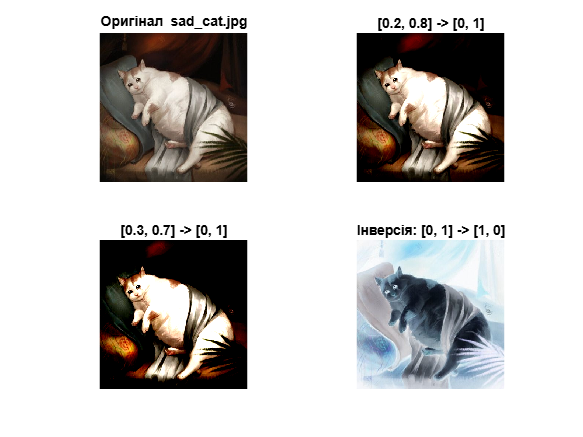


R = I_custom(:,:,1);
G = I_custom(:,:,2);
B = I_custom(:,:,3);

%% Приклад 1: Сильне розтягнення контрасту
R_adj1 = imadjust(R, [0.2 0.8], [0 1]);
G_adj1 = imadjust(G, [0.2 0.8], [0 1]);
B_adj1 = imadjust(B, [0.2 0.8], [0 1]);
cat_adj1 = cat(3, R_adj1, G_adj1, B_adj1);

%% Приклад 2: Менше розтягнення контрасту
R_adj2 = imadjust(R, [0.3 0.7], [0 1]);
G_adj2 = imadjust(G, [0.3 0.7], [0 1]);
B_adj2 = imadjust(B, [0.3 0.7], [0 1]);
cat_adj2 = cat(3, R_adj2, G_adj2, B_adj2);

%% Приклад 3: Інверсія зображення
R_adj3 = imadjust(R, [0 1], [1 0]);
G_adj3 = imadjust(G, [0 1], [1 0]);
B_adj3 = imadjust(B, [0 1], [1 0]);
cat_adj3 = cat(3, R_adj3, G_adj3, B_adj3);

figure;
subplot(2,2,1), imshow(I_custom), title('Оригінал sad\_cat.jpg');
subplot(2,2,2), imshow(cat_adj1), title('[0.2, 0.8] -> [0, 1]');
subplot(2,2,3), imshow(cat_adj2), title('[0.3, 0.7] -> [0, 1]');
subplot(2,2,4), imshow(cat_adj3), title('Інверсія: [0, 1] -> [1, 0]');